# Human Activity Classification Using Machine Learning

This is a supervised learning example.

Human activity sensor data contains observations derived from sensor measurements taken from smartphones worn by people while doing six different activities: Walking, Sitting, Laying, Standing, Walking Upstairs, and Walking Downstairs. 

The goal of this example is to build a classifier that can automatically identify the activity type given the sensor measurements. **In this supervised learning example, we will work with labeled data and features. **

**This example is based on the unsupervised learning example (Human Activity Clustering) and will NOT run on it's own.**

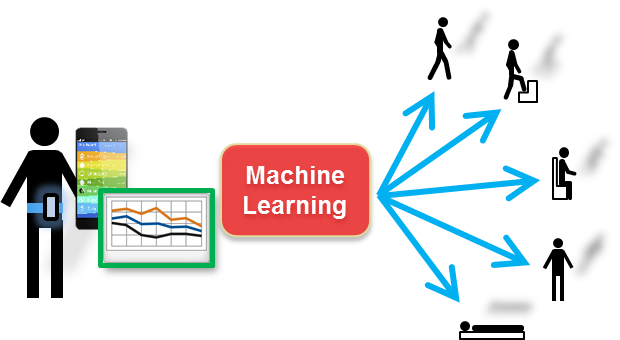

## Explore train and test data

### Train data

In the previous exercise, we loaded already the train data. And we also extracted some features (mean, std). 

Looking at the summary of the train data, we can see that we have approx. 1000 samples for each activity.

summary(trainActivity)

### Test data

We will pass the test data set through our model in order to evaluate it after the training. The test data set needs to be of the same format as the train data set. Therefore, we need to extract the same features as we did with the train data. Therefore, we'll do the same steps as for the train data.

The test data set contains of 2947 samples and approx. 500 samples for each activity.

Note: Loading the test data will overwrite the train data variables (t`otal_acc_x`, etc.) since they have the same names.

load('rawSensorData_test.mat')
summary(testActivity)
accX_mean = mean(total_acc_x, 2);
accY_mean = mean(total_acc_y, 2);
accZ_mean = mean(total_acc_z, 2);
gyroX_mean = mean(body_gyro_x, 2);
gyroY_mean = mean(body_gyro_y, 2);
gyroZ_mean = mean(body_gyro_z, 2);

accX_std = std(total_acc_x, [], 2);
accY_std = std(total_acc_y, [], 2);
accZ_std = std(total_acc_z, [], 2);
gyroX_std = std(body_gyro_x, [], 2);
gyroY_std = std(body_gyro_y, [], 2);
gyroZ_std = std(body_gyro_z, [], 2);

% combine in one singel array
ActivityDataTest = [accX_mean accY_mean accZ_mean accX_std accY_std accZ_std ...
    gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std];

% clear variables (to keep workspace clean)
clear accX_mean accY_mean accZ_mean accX_std accY_std accZ_std gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std

## Train models

Use the [Classification Learner App](matlab: web(fullfile(docroot, 'stats/classificationlearner-app.html'))) to interactively train, compare and select classifiers. One of the biggest challenges in machine learning is that there are many different machine learning algorithms that could be applied to the same problem, and there is no way of knowing ahead of time which will work best. The Classification Learner App gives us an easy way to try out many different modeling techniques very quickly.

To open the Classification Learner App, you can either run the command below or go to APPS and click on  .

classificationLearner

Step 1: Start a `New Session` and choose the variables `From Workspace.`

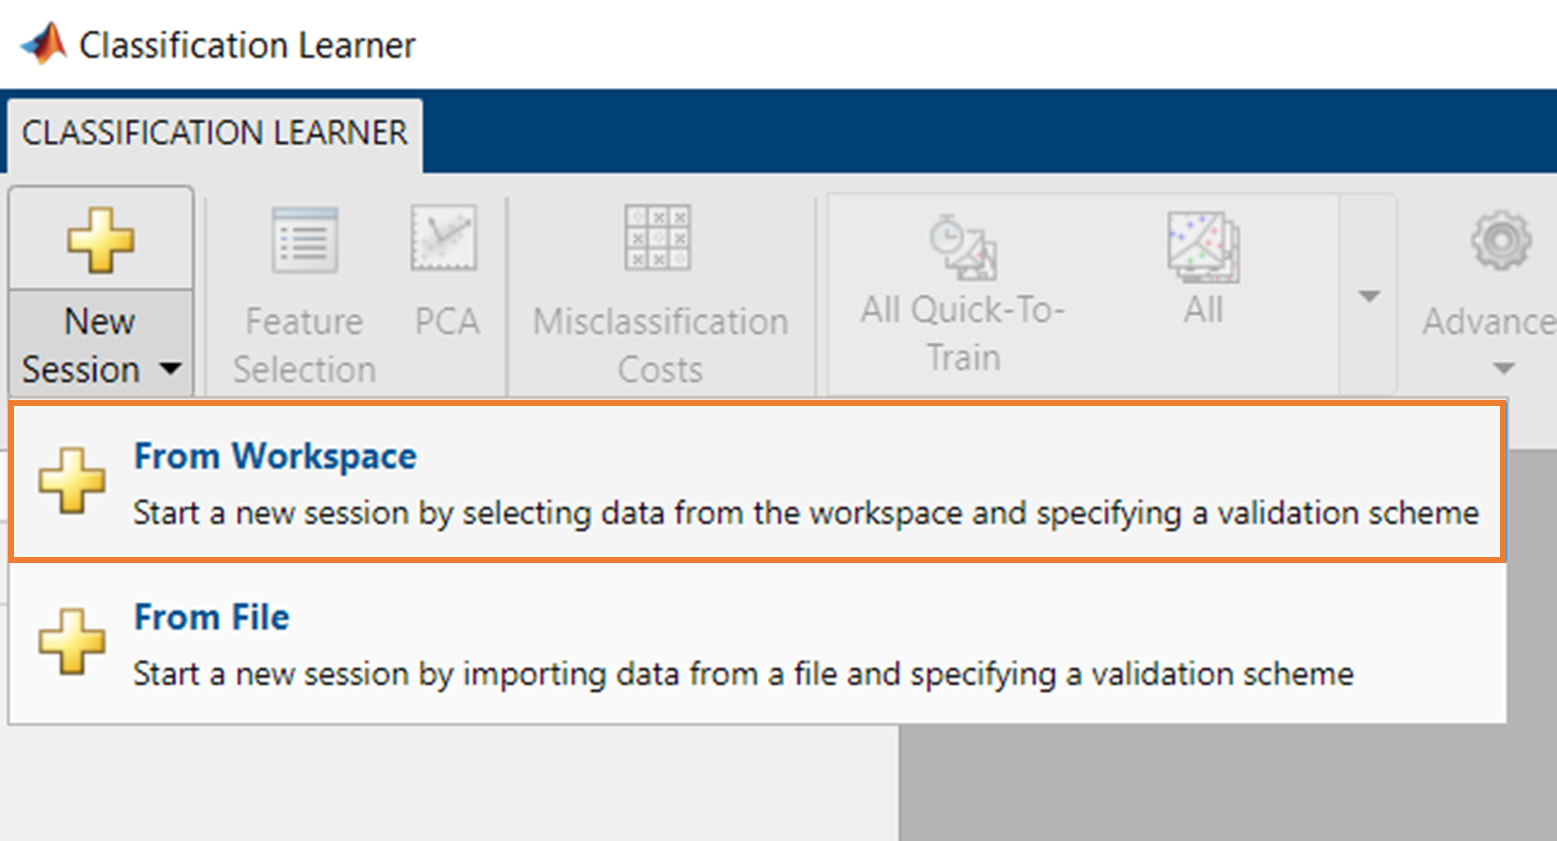

Choose `ActivityDataTrain` variable from the workspace as your *Data Set Variable*. Select the *Response* variable *From workspace*, and select `trainActivity`. Keep `Validation` section as it is (`Cross-Validation` with `5 folds`) and click on `Start Session`.

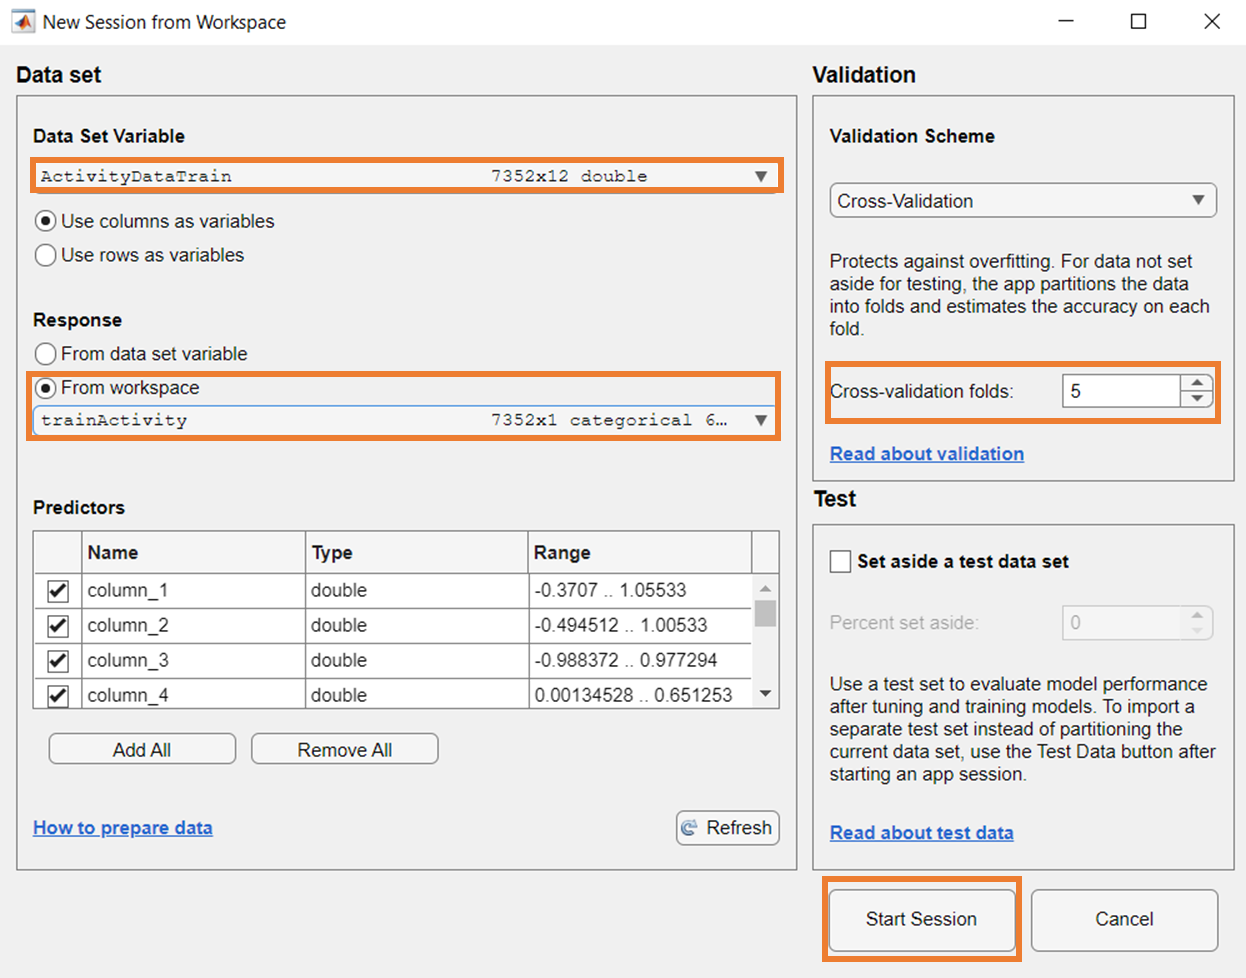

Step 2: In MODELS, choose `All Quick-To-Train` and start training by clicking on `Train ` . The training should take only a couple of seconds.

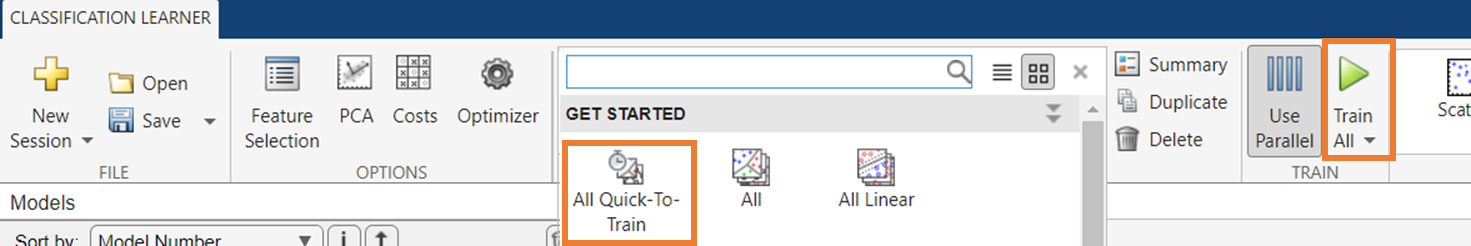

In the `Models `window, you should see the training progress and when done, the final (validation) accuracy of each model. The highest accuracy is highlighted in bold. Your results should look similar to this:

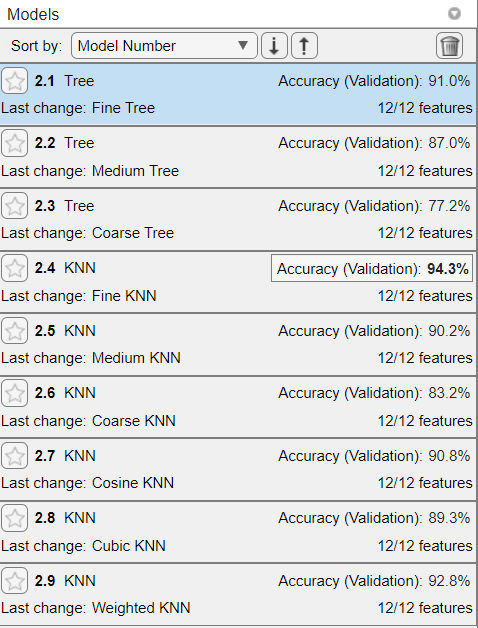

Step 3: Explore the confusion matrices of each model by clicking on the individual model and on `Confusion Matrix.`

## Evaluate trained model 

You can evaluate the performance of each model on unseen data (test data).

Load the test data set by clicking on the* Test Data *dropdown menu and choosing *From Workspace. S*elect `ActivityDataTest` as *Test Data Set Variable* (make sure that the *Response* variable is `testActivity`) and click on *Import*`.`

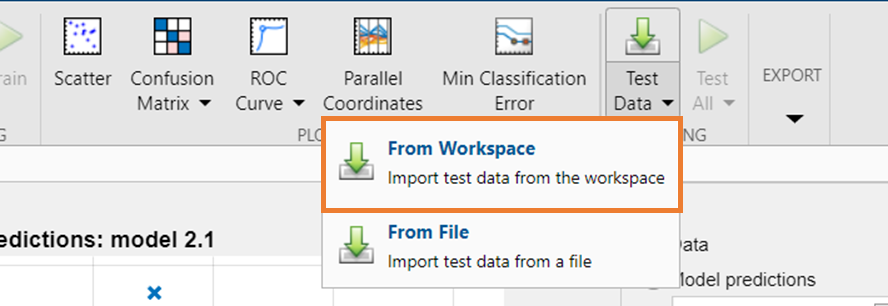

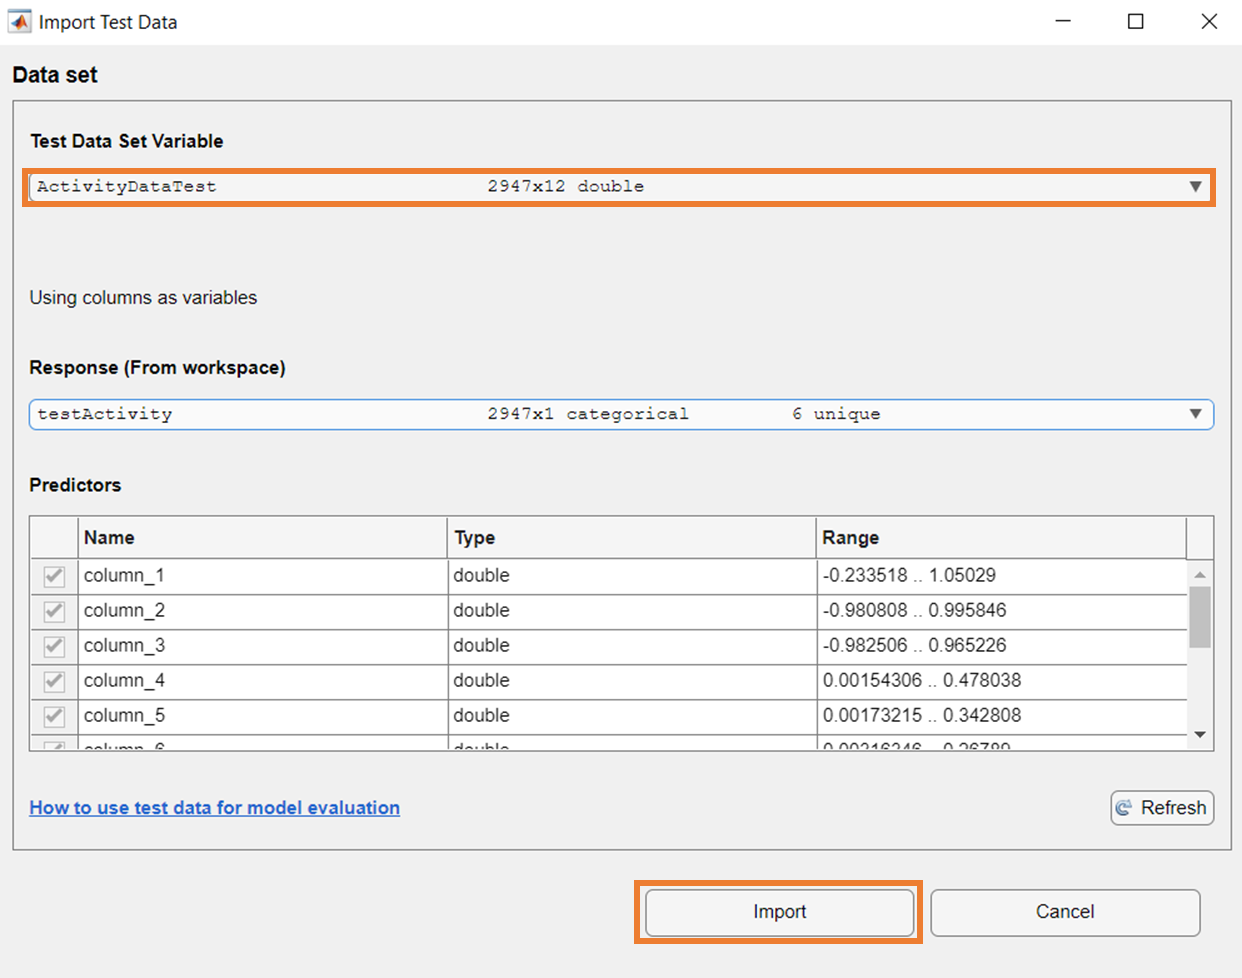

Choose a model you want to evaluate the performance of by clicking on the Star Button (*Add to favorites*) and clicking on *Test Selected* in the **Test All** dropdown menu. Alternatively, do not select any models and click on *Test All*`. When done, `the accuracy in the *Model window* will change to *Accuaracy(Test)*. Your results should look similar to this:

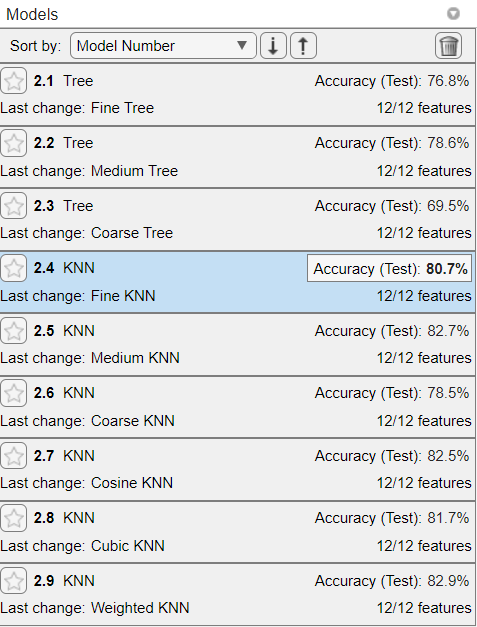

You can use the confusion matrix to visualise where the model got wrong on the test data.

## Export model

You can export your model by clicking on `EXPORT` and selecting *Export Model*. You can rename your model if you'd like to. Your trained model will appear in the workspace.

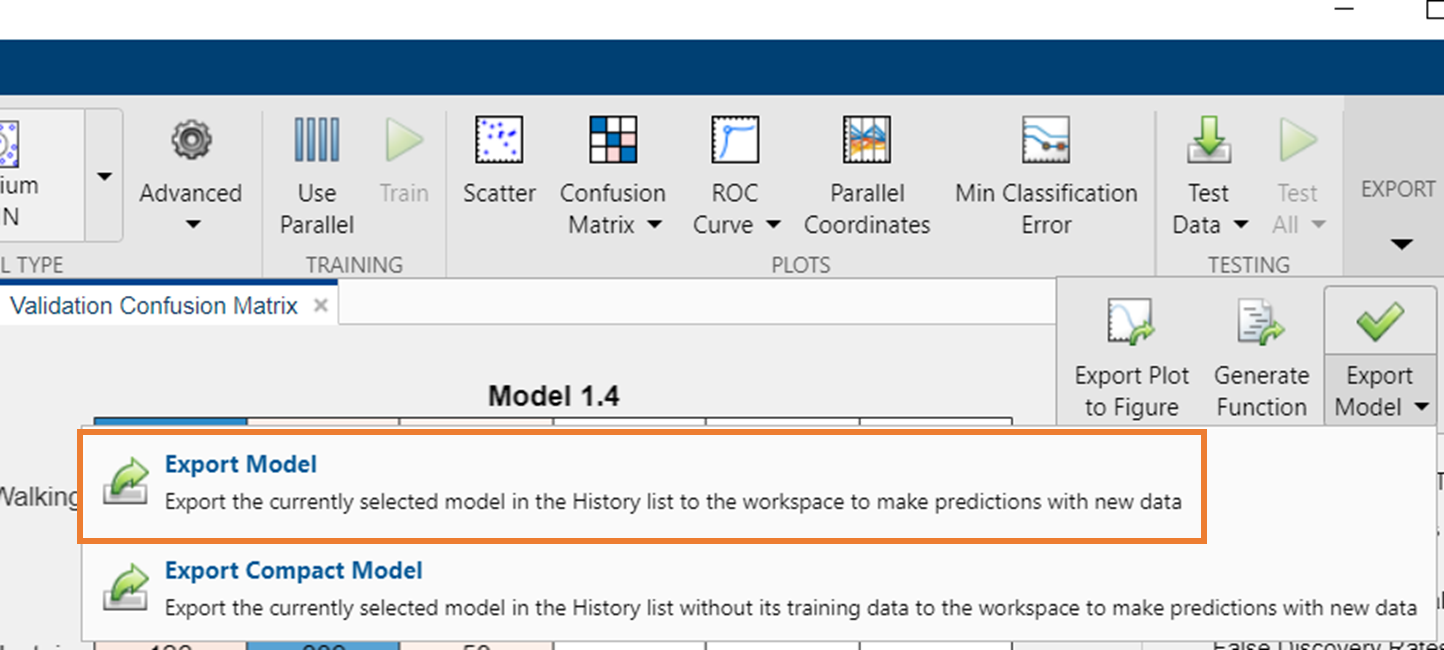

Alternatively, you can generate a function for further use by clicking on `Generate Function` (a new window will open with the function). The generated function also shows you how the previously described steps can be done programmatically.

## Summary and next steps

In this example we built machine learning models to classify human activity data which was acquired from a mobile phone. We extracted basic features applying statistical measures, interactively trained a few models with the Classification Learner App, and compared the performance.

Clearly we haven’t satisfactorily solved this problem, with the highest test accuracy still around 81%. Here are some additional steps you could try to improve accuracy: 

- Better features: By leveraging knowledge of signal processing, you can extract more powerful features. [Here's](https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/submissions/54139/versions/2/previews/html/DataClumsing.html) one example you could use.

- Hyperparameter tuning: Each model has parameters that need to be set just right to achieve optimal performance. [Here's](https://www.mathworks.com/help/stats/hyperparameter-optimization-in-classification-learner-app.html) an example how you can optimize the hyperparameters within the Classification Learner App. And [here](https://www.mathworks.com/help/stats/bayesian-optimization-algorithm.html) is more information on how to perform Bayesian Optimization. Alternatively, we can automatically select a classification model with optimized hyperparameters using the "[fitcauto](matlab: web(fullfile(docroot, 'stats/fitcauto.html')))" function in order to improve classifier performance. You can find more information on AutoML [here](https://www.mathworks.com/discovery/automl.html).

- You can try deep learning (see HumanActivityClassification_DL.mlx)

*Copyright 2022, The MathWorks, Inc.*